%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Analyze sample data - 24/06/2019                  %
% Arkadi Rafalovich - % Arkadiraf@gmail.com         %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc
clear

% Setup description
%{
Mic Speaker distance 0.5m
Supply voltage to Speaker 12V
Mic gain 4, mic thresh 50%
Scan 1-100 khz HPF Filter Board at 48Khz, xi 0.5 second order 
Op-Amp Speaker Gain is set to 1 (no gain, verified with scope) 
Test with Vifa speaker.
Test with SMD microphone

Data:
analog_channel_0  - Mic Select
analog_channel_1  - Output Signal
%}

## Open Data

%Open Recording
%load HPF_Off.mat
%Open Recording
load HPF_On.mat

%open position selected data
load PosSig.mat


## Variables

%time vector for plots
time_vector = ((1:1:size(analog_channel_0,1))/analog_sample_rate_hz)';

%sample time
Ts = 1/analog_sample_rate_hz;

% Remove Bias from signals
micSignal       =   analog_channel_0-mean(analog_channel_0);
outputSignal    =   analog_channel_1-mean(analog_channel_1);


## Select Position Signal

% PosSig = outputSignal(361800:(364600-1));
% use only the 25khz signal
% PosSig = outputSignal(361800:(363072-1));
% save PosSig PosSig
% plot(outputSignal)
% [x]=ginput(2)
% PosSig=micSignal(x(1):x(2))

## Recorded signals

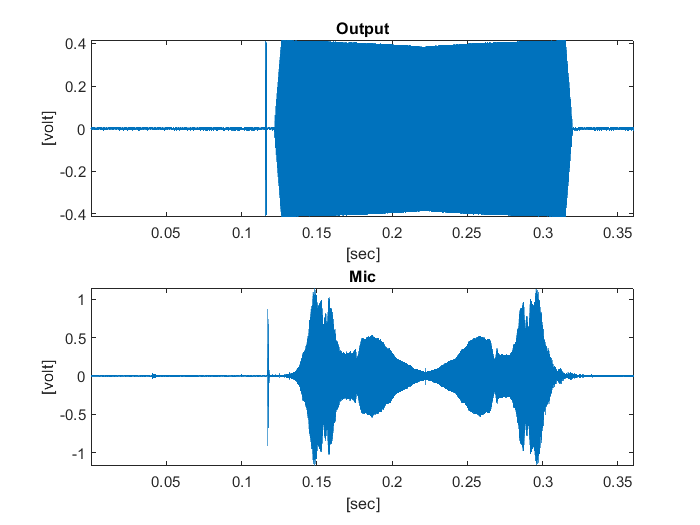

figure(1); % time response

subplot(2,1,1)
plot(time_vector,outputSignal)
title('Output');
axis tight
xlabel('[sec]');
ylabel('[volt]');

subplot(2,1,2)
plot(time_vector,micSignal)
title('Mic');
axis tight
xlabel('[sec]');
ylabel('[volt]');

## Find Signal Delay

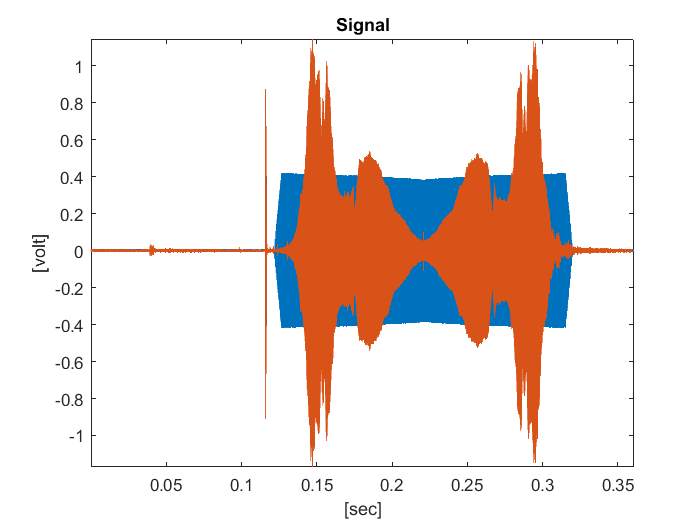

% Variables
signalCrossingValue = 0.5; % percentage of the max value from the signal
numSamplesBeforeIndex = 1000; % number of samples used before crossing index
numSamplesAfterIndex = 2500; % number of samples used after crossing index
% filter signal before looking for the delay 
bpFilt = designfilt('bandpassiir', 'FilterOrder', 20, 'HalfPowerFrequency1', 20000, 'HalfPowerFrequency2', 60000, 'SampleRate', analog_sample_rate_hz);
%fvtool(bpFilt) % visualize filter response

% apply filter
outputSignalFiltered = filter(bpFilt,outputSignal);
micSignalFiltered = filter(bpFilt,micSignal);
% find position signal
outputSignal_Index = find(outputSignalFiltered > max(outputSignalFiltered)*signalCrossingValue,1,'first');
micSignal_Index = find(micSignalFiltered > max(micSignalFiltered)*signalCrossingValue,1,'first');
% generate array for cross correlation
outputSignalPos = outputSignal(outputSignal_Index - numSamplesBeforeIndex : outputSignal_Index + numSamplesAfterIndex);
micSignalPos = micSignal(micSignal_Index - numSamplesBeforeIndex : micSignal_Index + numSamplesAfterIndex);
% find signal delay
delayOutput = finddelay(PosSig,outputSignalPos) + outputSignal_Index - numSamplesBeforeIndex;
delayMic = finddelay(PosSig,micSignalPos) + micSignal_Index - numSamplesBeforeIndex;

% generate signal to mark the delay
markDelay = [zeros(delayOutput,1) ; ones(delayMic-delayOutput,1) ; zeros(size(micSignal,1)-delayMic,1)];

figure(3); % Signal delay
plot(time_vector,outputSignal)
hold on
plot(time_vector,micSignal)
plot(time_vector,markDelay)
hold off
title('Signal');
axis tight
xlabel('[sec]');
ylabel('[volt]');

% adjust signals
micSignalAdjusted = [micSignal(delayMic-delayOutput : end) ; zeros(delayMic-delayOutput-1,1)];

% Select signals sweep
micSignalSweep = micSignalAdjusted(delayOutput + numSamplesAfterIndex + numSamplesBeforeIndex : end);
outputSignalSweep = outputSignal(delayOutput + numSamplesAfterIndex + numSamplesBeforeIndex : end);
timeVectorSweep = time_vector(delayOutput + numSamplesAfterIndex + numSamplesBeforeIndex : end);

figure(4); % signals delayed
plot(time_vector,outputSignal)
hold on
plot(time_vector,micSignalAdjusted)
hold off
title('Signal');
axis tight
xlabel('[sec]');
ylabel('[volt]');

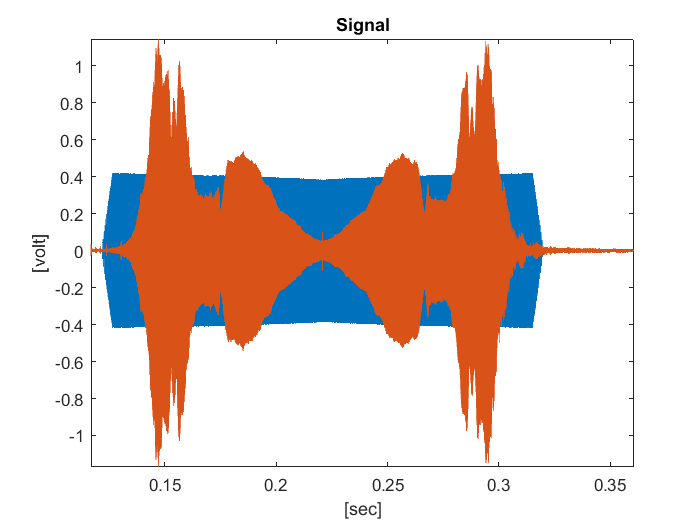


figure(5); % signals delayed
plot(timeVectorSweep,outputSignalSweep)
hold on
plot(timeVectorSweep,micSignalSweep)
hold off
title('Signal');
axis tight
xlabel('[sec]');
ylabel('[volt]');

## save recording

% save with HPF on
% HPF_on.timeVectorSweep = timeVectorSweep - timeVectorSweep(1);
% HPF_on.outputSignalSweep = outputSignalSweep;
% HPF_on.micSignalSweep = micSignalSweep;
% save HPFSweep_on HPF_on;

% % save with HPF off
% HPF_off.timeVectorSweep = timeVectorSweep - timeVectorSweep(1);
% HPF_off.outputSignalSweep = outputSignalSweep;
% HPF_off.micSignalSweep = micSignalSweep;
% save HPFSweep_off HPF_off;

## Spectogram

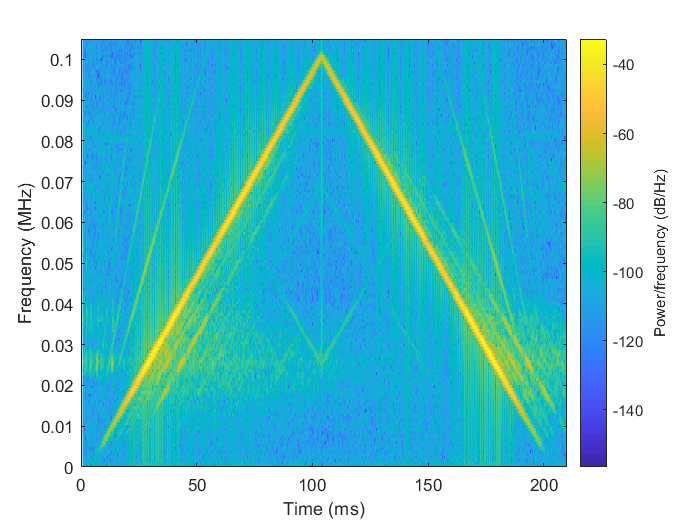

% Spectogram
figure(6); 
spectrogram(micSignalSweep,4096,4000,4096,analog_sample_rate_hz,'yaxis');
xlim([0 210]);
ylim([0 0.105]);

## System identification / Bode

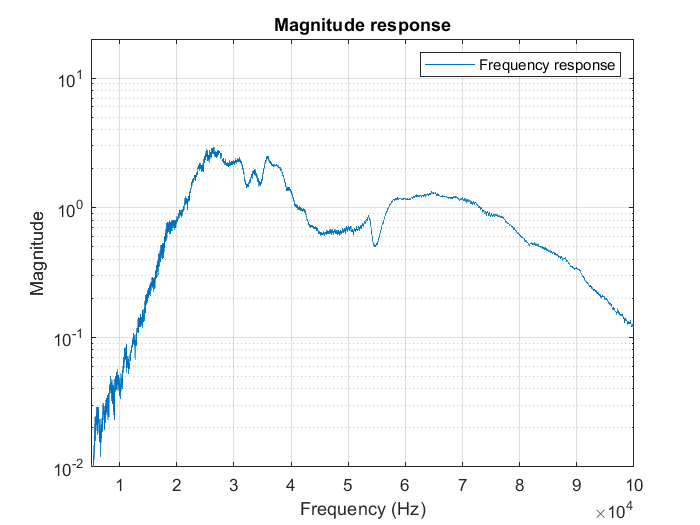

% Link https://www.mathworks.com/help/supportpkg/analogdevicesadalm1000/examples/estimate-the-transfer-function-of-a-circuit-using-live-measurements.html
% estimate bode
[TFxy,Freq] = tfestimate(outputSignalSweep, micSignalSweep,[],[],[],analog_sample_rate_hz);
%[TFxy,Freq] = tfestimate(micSignalSweep,outputSignalSweep,[],[],[],analog_sample_rate_hz);
Mag = abs(TFxy);
Phase = - rad2deg(unwrap(angle(TFxy)));
MagdB = 20*log10(Mag);

% plot ranges
sweepStart = 5e3;
sweepEnd = 100e3;

% plot Magnitude
figure(7);
semilogy(Freq,Mag);
xlim([sweepStart sweepEnd])
xlabel('Frequency (Hz)')
ylim([0.01 20])
ylabel('Magnitude')
grid on
legend('Frequency response')
title({'Magnitude response'});

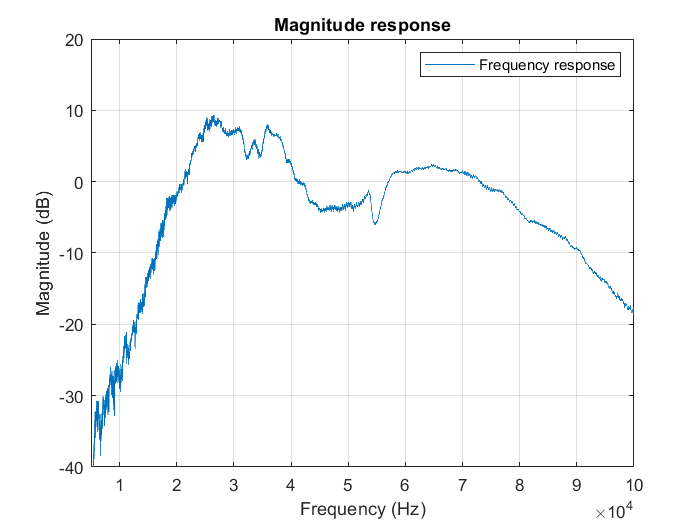



% plot magnitude dB
figure(8);
plot(Freq,MagdB);
xlim([sweepStart sweepEnd])
xlabel('Frequency (Hz)')
ylim([-40 20])
ylabel('Magnitude (dB)')
grid on
legend('Frequency response')
title({'Magnitude response'});

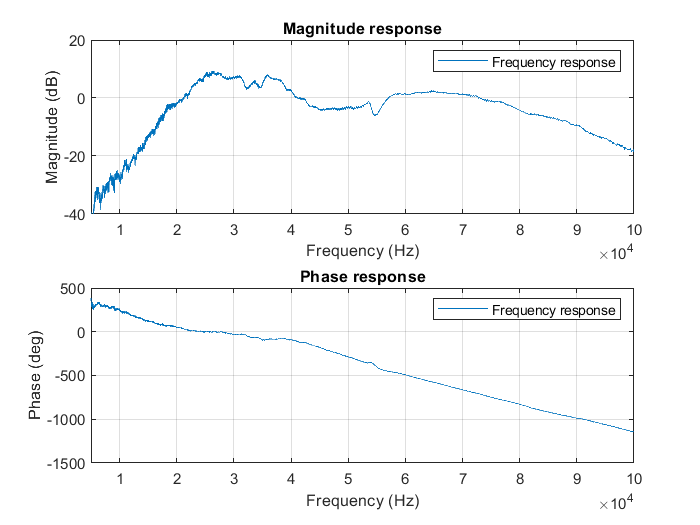

% Bode Plot
figure(10);

subplot(2,1,1);
plot(Freq,MagdB);
xlim([sweepStart sweepEnd])
xlabel('Frequency (Hz)')
ylim([-40 20])
ylabel('Magnitude (dB)')
grid on
legend('Frequency response')
title({'Magnitude response'});

subplot(2,1,2);
plot(Freq,Phase - Phase(find(Freq > 25e3,1,'first')))
xlim([sweepStart sweepEnd])
xlabel('Frequency (Hz)')
ylabel('Phase (deg)')
grid on
legend('Frequency response')
title({'Phase response'});